clear;
h=0.420;
wb=1.320;
dist_cg_rear=0.730;
mass=140+60;
weight=mass*9.8;
mew=0.7;
wheel_r=17*0.0254;

relative_cg=h/wb;
load_f=weight*(dist_cg_rear+mew*h)/wb;
load_r=weight*(wb-dist_cg_rear-mew*h)/wb;
f_per=load_f*100/weight;
r_per=load_r*100/weight;
deaccel=mew*9.8;
%%REQUIRED
total_bf=mass*deaccel*9.8;
front_bf=load_f*mew;
rear_bf=load_r*mew;
req_torque_f=front_bf*wheel_r

req_torque_f = 459.5818

req_torque_r=rear_bf*wheel_r

req_torque_r = 132.8478


%%calculations to achive required
pedal_force=300;
pedal_ratio=6;
bore_dia_tmc=0.018;
bore_dia_calliper=0.025;
mew_pad=0.42;

force_tmc=pedal_ratio*pedal_force;
area_tmc=pi*bore_dia_tmc*bore_dia_tmc/4;
pressure_tmc=force_tmc/area_tmc;

%%FRONT
area_calliper_f=pi*bore_dia_calliper*bore_dia_calliper/4;
force_calliper_f=2*mew_pad*pressure_tmc*area_calliper_f;
%%field that can be varied
dia_disk_o_f=0.3:0.01:0.6

dia_disk_o_f =     0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900    0.5000    0.5100    0.5200    0.5300    0.5400    0.5500    0.5600    0.5700    0.5800    0.5900    0.6000


dia_disk_i_f=0:0.01:0.2

dia_disk_i_f =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000


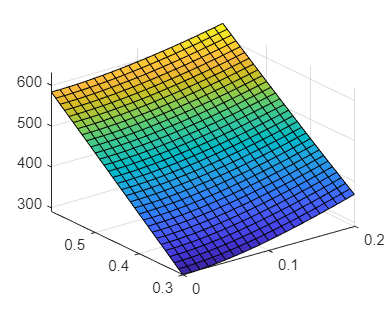


eff_rad_f=zeros(size(dia_disk_o_f,2),size(dia_disk_i_f,2));
for i=1:size(dia_disk_o_f,2)
    for j=1:size(dia_disk_i_f,2)
        eff_rad_f(i,j)=(dia_disk_o_f(i).^3-dia_disk_i_f(j).^3)/(3*(dia_disk_o_f(i).^2-dia_disk_i_f(j).^2));
    end
end
eff_rad_f;
torque_f=eff_rad_f.*force_calliper_f;
surf(dia_disk_i_f,dia_disk_o_f,torque_f)